% Jep Brinkmann Thesis HMM example
clc; close all;

Initiate the HMM

k = number of states

d = number of possible observational values

T = transition matrix

O = emission matrix

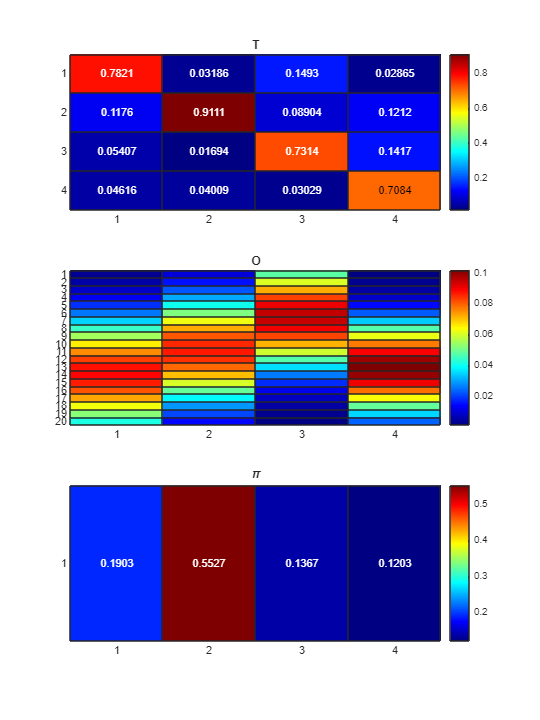

k = 4;
d = 20;

options.method = "random";
options.lambda = 10;

[T, O, pi, k, d] = generateHMM(k, d, 1, options);

figure('Renderer', 'painters', 'Position', [10 10 900 1200])


subplot(3, 1, 1);
h = heatmap(T, Colormap=jet());
h.Title = 'T';

subplot(3, 1, 2);
h = heatmap(O, Colormap=jet());
h.Title = 'O';

subplot(3, 1, 3);
h = heatmap(pi, Colormap=jet());
h.Title = '\pi';

Calculate true joint probability tensor $$P_3^\infty$$

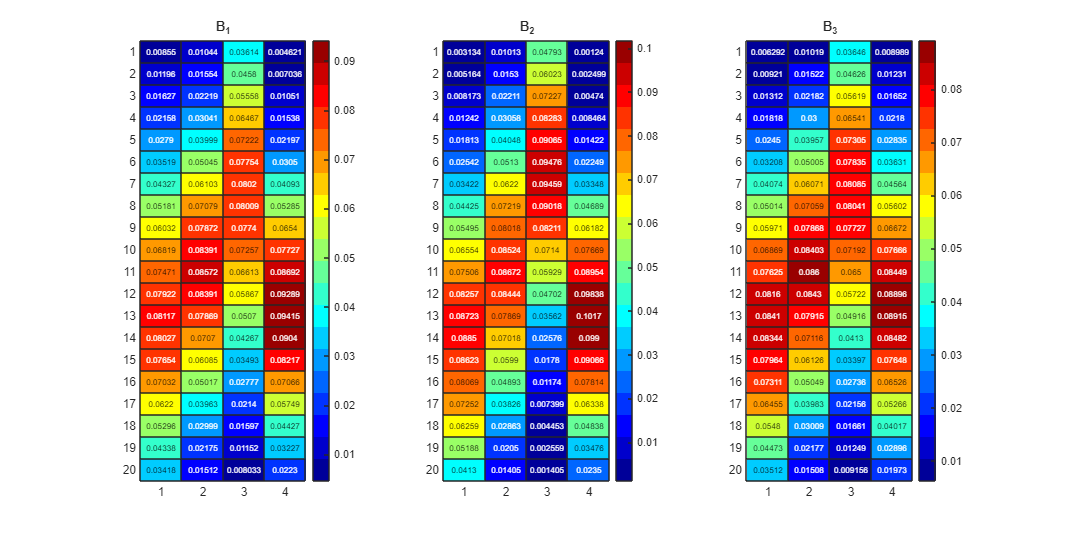


D = {};
D{1} = Stochasticize(O * diag(pi) * T' * inv(diag(T * pi')));
D{2} = O;
D{3} = Stochasticize(O * T);

P3_inf = cpdgen(D)/k;

PlotFactorMatrices(D);

Generate the joint probability tensor (JPT) $P_3^n$ by sampling n datasamples from the HMM matrices


T_seq = 1e5;

Taug = [0, pi; zeros(k, 1), T'];
Oaug = [zeros(1, d); O'];
[seq,states] = hmmgenerate(T_seq, Taug, Oaug);

tic
[P3_n, convergence] = estimate_joint_prob(seq, d, P3_inf);
toc

Elapsed time is 0.029277 seconds.


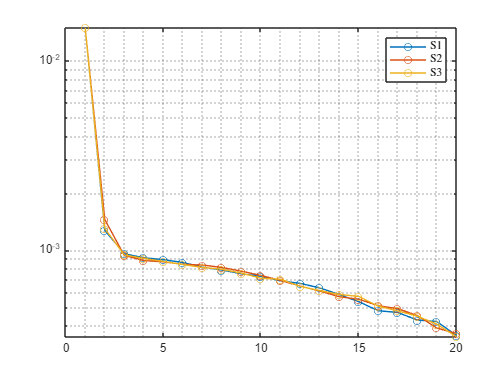

P = P3_n;


[C,U1,U2,U3] = mlsvd_3d(P);

T1 = mode_n_matricization(P, 1);
T2 = mode_n_matricization(P, 2);
T3 = mode_n_matricization(P, 3);

[~,S1,~] = svd(T1);
[~,S2,~] = svd(T2);
[~,S3,~] = svd(T3);

figure()
semilogy(nonzeros(S1), '-o'); hold on;
semilogy(nonzeros(S2), '-o'); hold on;
semilogy(nonzeros(S3), '-o'); hold on;
grid minor; legend('S1','S2', 'S3')

rank_mode1 =3;
rank_mode2 =3;
rank_mode3 =3;

U1t = U1(:, 1:rank_mode1);
U2t = U2(:, 1:rank_mode2);
U3t = U3(:, 1:rank_mode3);
Ct = C(1:rank_mode1, 1:rank_mode2, 1:rank_mode3);

P_rec = rec_mlsvd_3d(Ct,U1t,U2t,U3t);

alpha = 1e-6;
P_rec = laplacian_smoothing_mle(P_rec, alpha);

tic
[Uhat, output] = cpd(P_rec, k);
toc

Elapsed time is 0.781151 seconds.


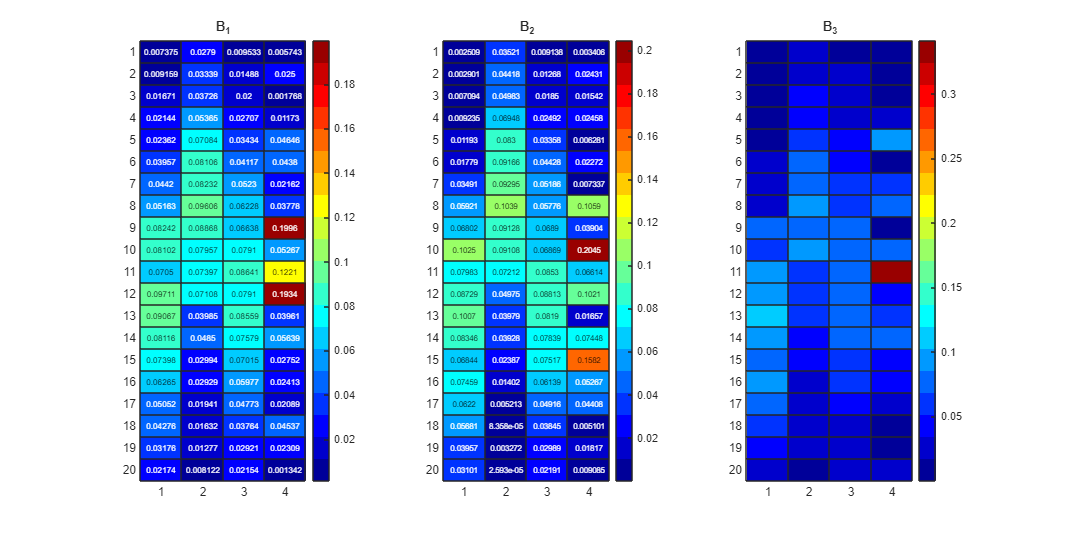


B1 = Stochasticize(Uhat{1});
B2 = Stochasticize(Uhat{2});
B3 = Stochasticize(Uhat{3});



PlotFactorMatrices({B1, B2, B3});

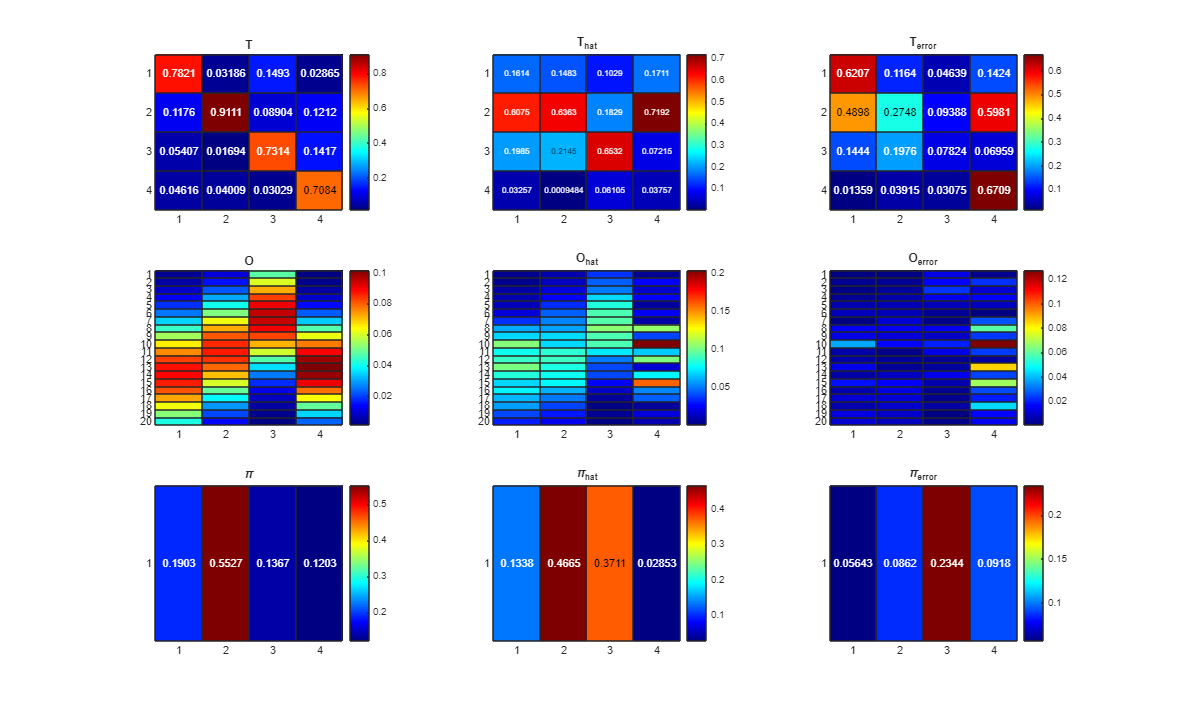

[T_hat, O_hat, pi_hat] = FactorMatrices2HMM({B1, B2, B3});
[T_hat, O_hat, pi_hat] = remove_hmm_permutation_emission(O, T_hat, O_hat, pi_hat);


plotHMMError(T, T_hat, O, O_hat, pi, pi_hat);

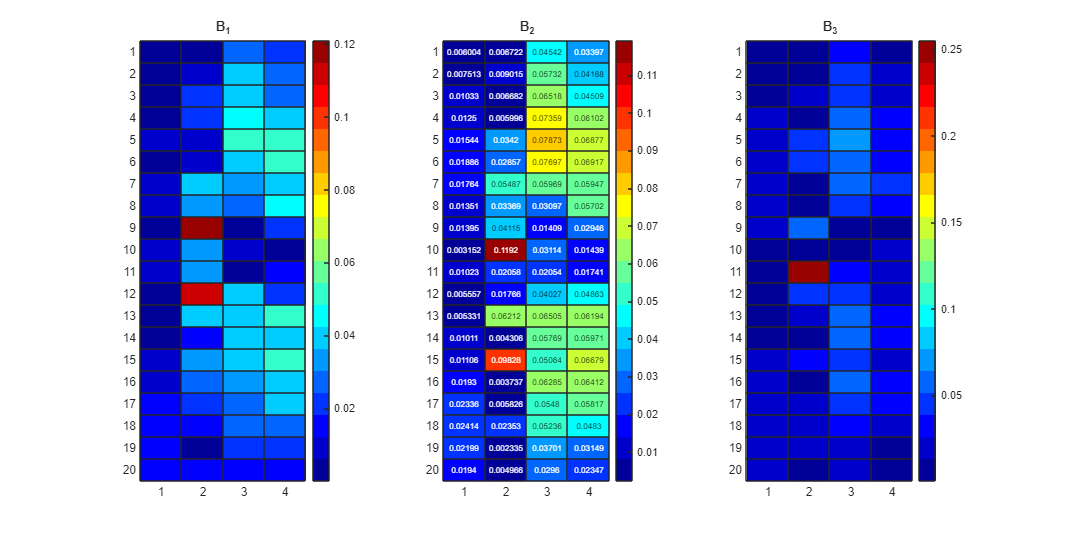

PlotFactorMatrices({abs(D{1} - B1*Pbest'), abs(D{2} - B2*Pbest'), abs(D{3} - B3*Pbest')});